uiimport("/MATLAB Drive/MATLAB Course Files/Section 2/counties.xlsx")
counties

counties = 67x20 table
    FIPS      ANSICODE     Latitude    Longitude         CountyName          State     StateName     Population2010    HousingUnits2010     LandArea     WaterArea     Cases2010    Cases2011    Cases2012    Cases2013    Cases2014    Cases2015    Cases1    Cases2    CaseDensity
    _____    __________    ________    _________    _____________________    _____    ___________    ______________    ________________    __________    __________    

counties.CaseDensity = counties.Cases2010 ./ counties.LandArea;
sortedCounties = sortrows(counties, "CaseDensity", "descend")

sortedCounties = 67x20 table
    FIPS      ANSICODE     Latitude    Longitude         CountyName          State      StateName      Population2010    HousingUnits2010     LandArea     WaterArea     Cases2010    Cases2011    Cases2012    Cases2013    Cases2014    Cases2015    Cases1    Cases2    CaseDensity
    _____    __________    ________    _________    _____________________    _____    _____________    ______________    ________________    __________    __________

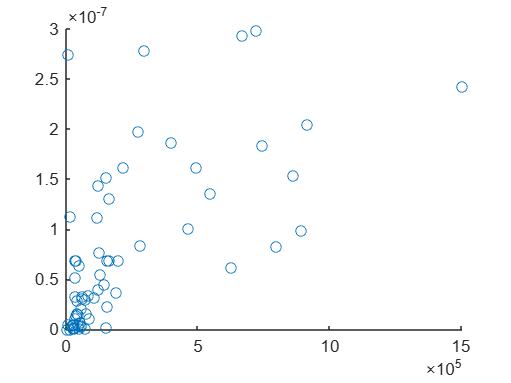

scatter(counties.Population2010, counties.CaseDensity)